clear;
close all;
reference_motor = 0.3;
max_freq = 100;

filename = 'Test5/160.csv';
test_data = csvread(filename, 2, 0);
refer_idx = find(test_data(:, 14) >= reference_motor, 1);
reference_time = test_data(refer_idx, 1); % test_data(1, 1)
test_data(:, 1) = test_data(:, 1)-reference_time; % reset start time

isp = refer_idx + 1* max_freq;
iep = find(test_data(:, 14) >= reference_motor,1,'last') - 2 * max_freq;
test_data = test_data(isp:iep, :);

ground_truth = test_data(:, 2:13);
gt_t = test_data(:, 1) * 1e-6;

max_freq = 400

max_freq = 400

filename2 = 'Test5_rerun/00000314.csv';
test_data2 = csvread(filename2, 2, 0);
refer_idx = find(test_data2(:, 14) >= reference_motor, 1);
reference_time = test_data2(refer_idx, 1); % test_data2(1, 1)
test_data2(:, 1) = test_data2(:, 1)-reference_time; % reset start time

isp = refer_idx + 1* max_freq;
iep = find(test_data2(:, 14) >= reference_motor,1,'last') - 2 * max_freq;
test_data2 = test_data2(isp:iep, :);

rerun = test_data2(:, 2:13);
rerun_t = test_data2(:, 1) * 1e-6;

[res_gt, res_gt_t] = resample(ground_truth, gt_t, max_freq);
[res_rerun, res_rerun_t] = resample(rerun, rerun_t, max_freq);

N = min(length(res_gt_t), length(res_rerun_t)) - 2;
res_gt = res_gt(1:N, :);
res_gt_t = res_gt_t(1:N);
res_rerun = res_rerun(1:N, :);
res_rerun_t = res_rerun_t(1:N);



errors = res_rerun - res_gt;
errors(:, 4:6) = wrapToPi(errors(:, 4:6));

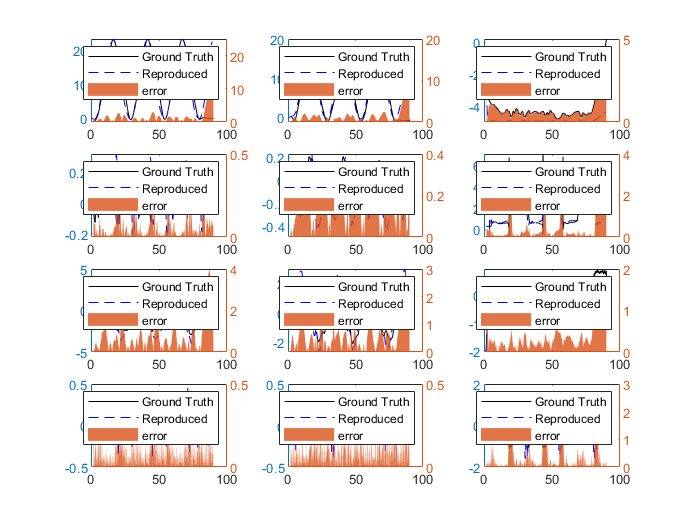

figure;
NY=12;
for n=1:NY
    if NY > 1
        subplot(NY/3, 3, n);
    end    
    yyaxis left
    plot(res_gt_t, res_gt(:, n),'k-');     %truth
    hold on;
    plot(res_rerun_t, res_rerun(:, n), 'b--');                  %model prediction
    hold on;
    yyaxis right
    area(res_gt_t, abs(errors(:, n)), 'FaceAlpha', 0.8, 'EdgeColor', 'none');    % deviation
    legend('Ground Truth', 'Reproduced', 'error');
end

distance_err = abs(errors(:, 1:3));
angles_err = rad2deg(abs(errors(:, 4:6)));
disp(['mean distance error: ' num2str(mean(distance_err)) ' m']);

mean distance error: 1.8397      1.5672     0.75253 m


disp(['mean angle errors: ' num2str(mean(angles_err)) ' degress']);

mean angle errors: 3.72831      9.79572      30.7487 degress


disp(['overall mean angle errors: ' num2str(mean(mean(angles_err))) ' degress'])

overall mean angle errors: 14.7576 degress


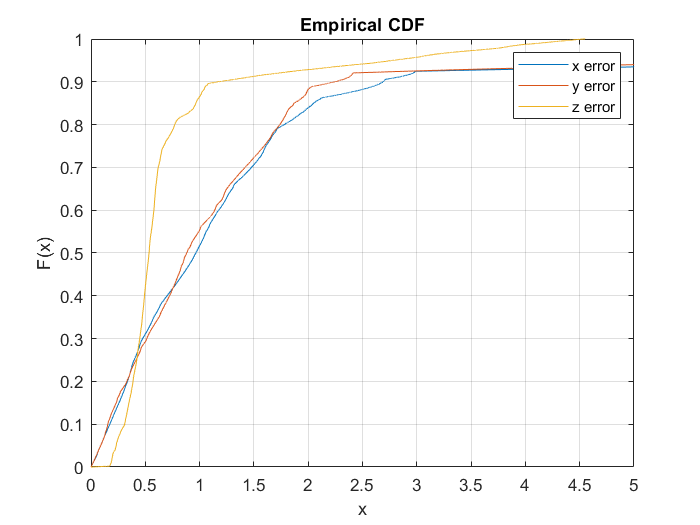

figure;
for i=1:3
    cdfplot(distance_err(:, i));
    hold on;
end
xlim([0, 5]);
legend({'x error', 'y error', 'z error'});

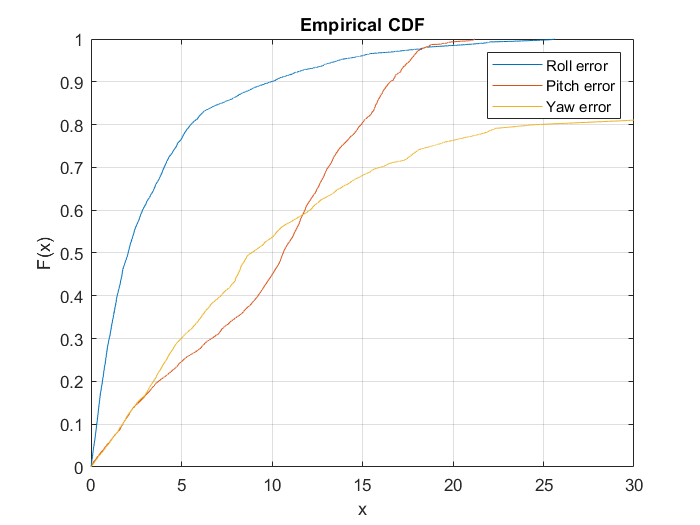

figure;
for i=1:3
    cdfplot(angles_err(:, i));
    hold on;
end
xlim([0, 30]);
legend({'Roll error', 'Pitch error', 'Yaw error'});